# fitlm Anwendungen

Die nachfolgenden Beispiele sollen verwendet werden, um die Verwendung von fitlm zu üben. Die Beispiele stammen aus ganz unterschiedlichen Anwendungsgebieten. Sie geben einen kleinen Einblick in die vielfältigen Einsatzmöglichkeiten dieser Methode.

## Energieverbrauch für das Heizen von Wasser

In einem Schüler-Praktikum wurde diese Messsung gemacht um die spezifische Wärmekapazität des Wassers zu bestimmen.

***fitlm_daten\EnergieH2oTemp.csv***

Machen Sie eine Analyse mit fitlm

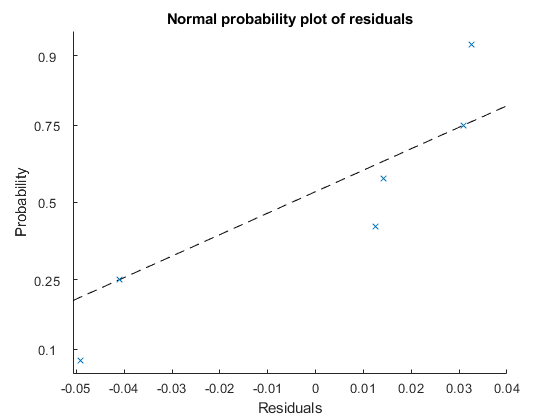

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = [ "Energy", "Temperature"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
H2O_Heizen = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\EnergieH2oTemp.csv", opts);

model1 = fitlm(H2O_Heizen.Energy, H2O_Heizen.Temperature);

plotResiduals(model1, "probability");

## Laufgeschwindigkeit vs. Herzfrequenz

In einem Fittnesstest wurden nachfolgende Daten aufgezeichnet: ***fitlm_daten\Conconi.csv***

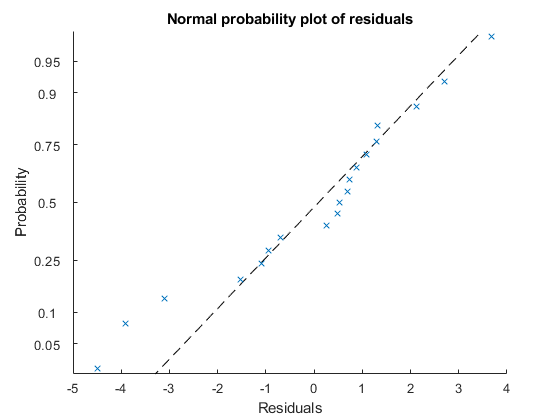

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Row", "Speed", "Puls"];
opts.VariableTypes = ["int16", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
conconi = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\Conconi.csv", opts);

model2 = fitlm(conconi.Speed, conconi.Puls);

plotResiduals(model2, "probability");

## Zusammenhang Alter zu Preis bei Antiken Uhren

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Observation", "Alter", "Preis"];
opts.VariableTypes = ["int16", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
antikeUhren = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\antikeUhren.csv", opts);

## Zusammenhang Temperatur-Differenz Aussen/Innen zu Verbrauch

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Observation", "temp", "verbrauch"];
opts.VariableTypes = ["int16", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
TempVsUsage = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\gas.csv", opts);

### Wodurch wird der Benzin-Verbrauch von Autos pro 100 km beeinflusst?

Welche Prediktoren scheinen Ihnen glaubhaft? Versuchen Sie aus. 

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 12);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Observation", "L_100km", "hubraum", "cyl", "ps", "drat", "wt", "qsec", "vs", "am", "gear", "carb"];
opts.VariableTypes = ["int16", "double", "double","double", "double", "double", "double", "double", "categorical","categorical","categorical","categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
HpVsFuel = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\ps_benzin.csv", opts);

## Ozongehalt im Zusammenhang mit Sonneneinstrahlung, Temperatur und Wind

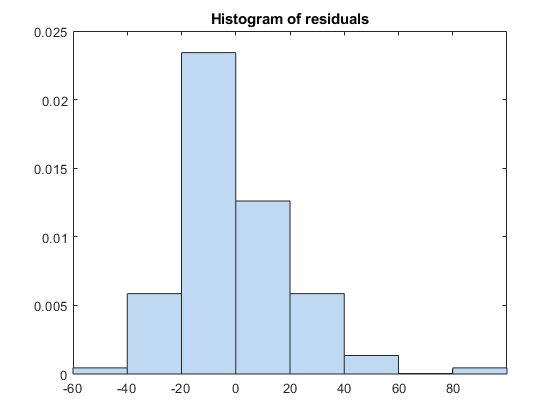

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Observation", "Ozone", "Solar_R", "Wind", "Temp", "Month", "Day"];
opts.VariableTypes = ["int16", "double", "double", "double", "double", "categorical", "int16"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Ozone", "Solar_R"], "EmptyFieldRule", "auto");

% Import the data
airquality = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\airquality.csv", opts);

model2 = fitlm([airquality.Temp, airquality.Wind, airquality.Solar_R], airquality.Ozone);

%plotResiduals(model, "probability");
plotResiduals(model2)